cd F:\ResearchMainStream\0.ResearchBySection\C.动力学模型\参数优化\参数优化实现\并行化参数扫略计算SIMPACK模型临界速度\结果分析组\L123网格扫描结果

clc
clear

X_vars_fromPython = readNPY('myXvars_123.npy');
CriticalVel_fromPython = readNPY('myCriticalVel_123.npy');


### 首先，检查 Lx3=0 的计算正确性

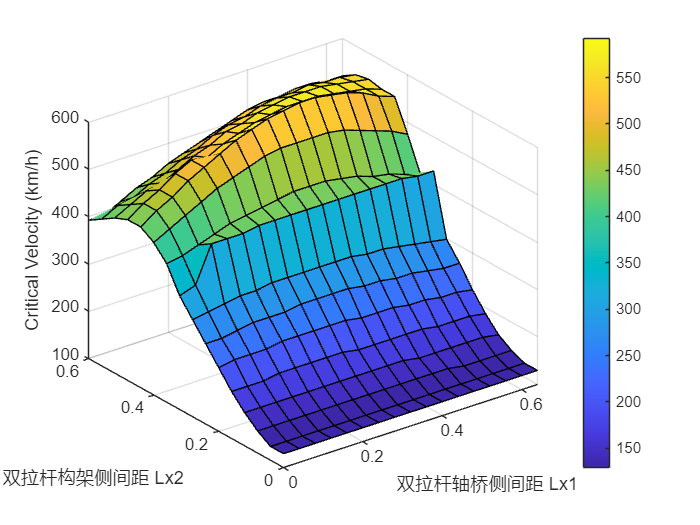

% 在 MATLAB 中重现同样的采样点
Lx1_sweep = 0 : 0.04 : 0.64;   % 17 个点
Lx2_sweep = 0 : 0.04 : 0.60;   % 16 个点
Lx3_sweep = -0.6 : 0.1 : 0.4;  % 11 个点

% 设置容忍度 (tol)
tol = 1e-10;

% 找到“接近0”的 Lx3 索引
index_Lx3_zero = find(abs(X_vars_fromPython(32, :) ) < tol); % Python数据不精确等于0

% 对应的 CriticalVel
CriticalVel_Lx3Eqzero = CriticalVel_fromPython(index_Lx3_zero);

%% reshape 成二维矩阵进行作图
% 注意，这里假设 itertools.product(Lx1_sweep, Lx2_sweep, Lx3_sweep) 的顺序。
% (具体细节可参见之前回答中的说明)
Lx1_sweep = 0 : 0.04 : 0.64;  % 17
Lx2_sweep = 0 : 0.04 : 0.60;  % 16

nLx1 = length(Lx1_sweep);  % 17
nLx2 = length(Lx2_sweep);  % 16

CriticalVel_2D = reshape(CriticalVel_Lx3Eqzero, [nLx2, nLx1]);


% 三维可视化
figure();
[X, Y] = meshgrid(Lx1_sweep, Lx2_sweep);  % X大小: length(Lx2_sweep)-by-length(Lx1_sweep)
Z      = CriticalVel_2D * 3.6;              % 将criticalVel_m_s转置，以匹配X, Y大小
surf(X, Y, Z);                           % 绘制三维表面
xlabel('双拉杆轴桥侧间距 Lx1');
ylabel('双拉杆构架侧间距 Lx2');
zlabel('Critical Velocity (km/h)');
colorbar;     

%{
可视化方法2：可以运行

[Lx1_grid, Lx2_grid] = meshgrid(Lx1_sweep, Lx2_sweep);
subplot(1,2,1)
surf(Lx1_grid, Lx2_grid, CriticalVel_2D);
shading interp;
colorbar;
xlabel('Lx1');
ylabel('Lx2');
zlabel('CriticalVel');
title('CriticalVel 随 Lx1, Lx2 的变化 (当 Lx3 视为 0 时)');
%}

### 其次，画出热力图

Lx1、Lx2、Lx3 对于 CriticalVel 的影响的热力图

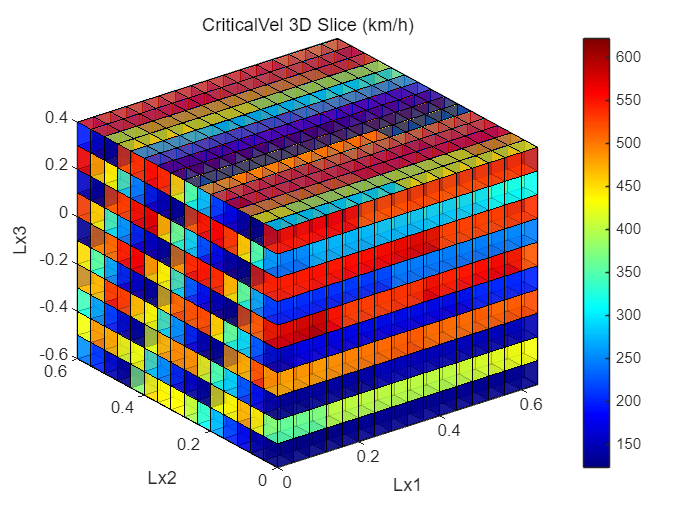

%% =============== 0. 准备工作：从 .npy 文件读数据 ====================
% 假设已经在当前文件夹里有 myXvars_123.npy 和 myCriticalVel_123.npy
% 需要先安装/添加第三方函数 readNPY.m（如果你之前已经有就不用了）
% 下载地址可参考：https://www.mathworks.com/matlabcentral/fileexchange/87106-npy-matlab


% 如果你知道 CriticalVel 的单位是 m/s，且希望转成 km/h:
CriticalVel_fromPython_kmh = CriticalVel_fromPython * 3.6;

nLx1 = length(Lx1_sweep);  % 17
nLx2 = length(Lx2_sweep);  % 16
nLx3 = length(Lx3_sweep);  % 11

%% =============== 2. 用 meshgrid 生成三维网格 (X, Y, Z) ==============
% 在 MATLAB 中：
%   [X, Y, Z] = meshgrid(x_sweep, y_sweep, z_sweep)
% 结果的尺寸是 [length(y_sweep), length(x_sweep), length(z_sweep)]
% 对应 [nLx2, nLx1, nLx3]。
[X, Y, Z] = meshgrid(Lx1_sweep, Lx2_sweep, Lx3_sweep);
% size(X) => [16, 17, 11]

%% =============== 3. reshape CriticalVel 为 3D，然后 permute =========
% 根据 Python 的 itertools.product(Lx1, Lx2, Lx3) 的顺序，一般先固定 Lx1，再 Lx2，再 Lx3。
% 因此：
%   reshape(CriticalVel, [nLx1, nLx2, nLx3]) => 大小 [17,16,11]
% 但上面 X, Y, Z 的大小是 [16,17,11]。
% 所以我们需要 permute 来对调前两维，使之变为 [16,17,11]。

CriticalVel_3D = reshape(CriticalVel_fromPython_kmh, [nLx1, nLx2, nLx3]);  % [17,16,11]
CriticalVel_3D = permute(CriticalVel_3D, [2, 1, 3]);                      % => [16,17,11]

%% =============== 4. 绘制三维切片图 (slice plot) =====================
figure('Name','3D Slice of CriticalVel');

% 根据自己的需要，指定在 x / y / z 方向分别切哪些平面：
% （下列数值仅为举例，请结合实际情况选定）
% xslices = [0.2, 0.4, 0.6];  % 在 Lx1=0.2, 0.4, 0.6 处做切片
% yslices = [0.2, 0.4];       % 在 Lx2=0.2, 0.4 处做切片
% zslices = [-0.2, 0, 0.2];   % 在 Lx3=-0.2, 0, 0.2 处做切片

xslices = Lx1_sweep;  % 在 Lx1=0.2, 0.4, 0.6 处做切片
yslices = Lx2_sweep;       % 在 Lx2=0.2, 0.4 处做切片
zslices = Lx3_sweep;   % 在 Lx3=-0.2, 0, 0.2 处做切片


% slice(X, Y, Z, V, xslices, yslices, zslices)
hSlices = slice(X, Y, Z, CriticalVel_3D, ...
    xslices, yslices, zslices);

% 可以设定插值方式： 'linear' / 'cubic' / 'nearest' ...
% hSlices = slice(X, Y, Z, CriticalVel_3D, xslices, yslices, zslices, 'cubic');

%% =============== 5. 调整绘图外观 ====================
% 下面这些是可选的，你可以根据需求增删

shading faceted;    % 带网格线 (wireframe)
% shading interp;   % 若想要平滑过渡，不显示网格线，取消上面这行，改用这一行

alpha(0.7);         % 设置半透明
colormap jet;       % 让低值呈蓝色，高值呈红色
colorbar;           % 显示颜色条
caxis([min(CriticalVel_3D(:)), max(CriticalVel_3D(:))]); % 颜色轴范围可根据需要调节

xlabel('Lx1');
ylabel('Lx2');
zlabel('Lx3');
title('CriticalVel 3D Slice (km/h)');
axis tight;        % 让坐标轴范围贴合数据
grid on; box on;   % 打开网格/坐标框